clear variables; close all; clc;

## **Assignment:**

Pick a different subset of data from the nextstrain site, download the metadata file and clean it up (see the process I noted I used at the top of this script), so it can be used to build a tree - you may wish to select only a subset of the data, for computational reasons (especially if the sequences are long).  Upload your metadata file with your assignment.  

## Load Data

Now we load two small pre-processed datasets, two different variants of the CoronaVirus : 

- Variant 22E-Omicron (September-November 2022)

- Variant 21I-Delta (May-November 2021)

Then join the two in a combined dataset.

Corona21I = load("corona21I_clean.mat")                     % load variant 21I

Corona21I = struct with fields:
    Corona21I: [14×6 table]


Corona22E = load("corona22E_clean.mat")                     % load variant 22E

Corona22E = struct with fields:
    Corona22E: [17×6 table]



CoronaViruses = [Corona21I.Corona21I;Corona22E.Corona22E]   % join two datasets

CoronaViruses = 31×6 table
                 strain                     date       genbank_accession         region              country        variant
    _________________________________    __________    _________________    _________________    _______________    _______

    {'BHR/342182341/2021'           }    2021-05-28      {'MZ506328'}       {'Asia'         }    {'Bahrain'    }    {'21I'}
    {'USA/MD-MDH-2657/2021'         }    2021-06-05      {'MZ438604'}       {'North America'}    {'USA'        }    {'21I'}
    {'AUT/SKV-219/2021'             }    2021-07-12      {'OL546707'}       {'Europe'       }    {'Austria'    }    {'21I'}
    {'USA/NC-CDC-LC0123151/2021'    }    2021-07-22      {'OK121865'}       {'North America'}    {'USA'        }    {'21I'}
    {'MWI/MLW000821/2021

[rows,columns] = size(CoronaViruses);                       % gather size

## Index strains with sequences

Now we make a last step in the pre-processing of our data by collecting all sequences indexed with the strain name, this will later be needed in order to build and label the phylogenetic tree.

sequences = cell(rows,1);                                       % sequencies array
names = cell(rows,1);                                           % labels array
for i=1:rows                                                    % for each sample
    access = string(CoronaViruses.genbank_accession(i));        % gather accession code
    variant = strcat("/",string(CoronaViruses.variant(i)));     % gather variant label    
    names{i} = strcat(CoronaViruses.strain(i),variant);         % gather strain label and concatenate variant
    gen = getgenbank(access);                                   % access and gather string sequence
    sequences{i} = gen.Sequence;                                % store gene sequence
end
data = struct("Name",names,"Sequence",sequences)                % collect above data in unique set

data = 31×1 struct array with fields:
    Name
    Sequence


## Distance Matrix 

Now we use the function **seqpdist** with **SquareForm** true to evaluate square matrix with the distances between sequences.

#### Note this is using parallel computing toolbox!

*remove UseParallel parameter to avoid it*

M = seqpdist(sequences,squareform=true,UseParallel=true)        % distance matrix

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


M =          0    0.0136    0.0179    0.0149    0.0142    0.0115    0.0129    0.0130    0.0187    0.0416    0.0129    0.0212    0.0204    0.0195    0.0936    0.0353    0.0525    0.0164    0.0263    0.0264    0.0936    0.0180    0.0282    0.0618    0.0897    0.0809    0.0164    0.0440    0.1038    0.0354    0.0708
    0.0136         0    0.0076    0.0035    0.0020    0.0025    0.0027    0.0029    0.0065    0.0329    0.0020    0.0089    0.0125    0.0113    0.0871    0.0258    0.0428    0.0071    0.0155    0.0158    0.0885    0.0087    0.0187    0.0519    0.0850    0.0764    0.0069    0.0342    0.0942    0.0247    0.0608
    0.0179    0.0076         0    0.0079    0.0072    0.0068    0.0059    0.0060    0.0127    0.0372    0.0061    0.0141    0.0095    0.0084    0.0890    0.0300    0.0471    0.0125    0.0199    0.0200    0.0903    0.0141    0.0220    0.0565    0.0861    0.0812    0.0119    0.0370    0.0990    0.0290    0.0654
    0.0149    0.0035    0.0079         0    0.0029    0.0038   

### Visualize Distance Matrix

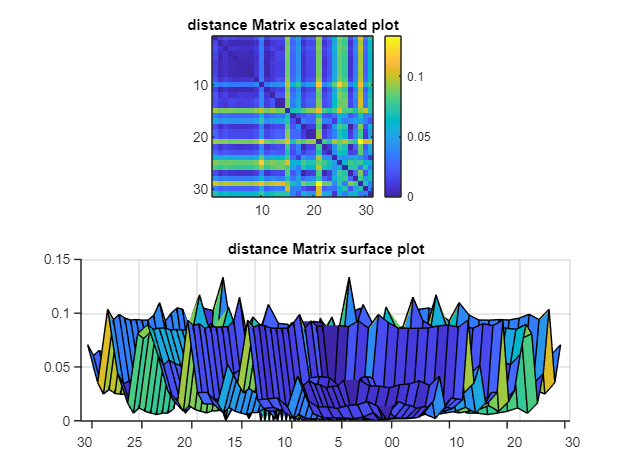

subplot(2,1,1); imagesc(M); daspect([1 1 1]); title("distance Matrix escalated plot");
colorbar
subplot(2,1,2); surf(M); view([-60 0]); title("distance Matrix surface plot"); 

The distance matrix tells us there is high correlation in the right/bottom part of the matrix, which intuitively represents the set coming from the 22E variant (index 15 to 31)

It is indeed expected high correlation between these samples because, looking at the original table where the country and region are stored, we can see that for this particular subset the samples all come from Kenya,Africa (not intentional from my side), and hence they have high chance to have less margin of variance.

While for the other subset (variant 22I index 1 to 14) the samples are collected from all around the world, and hence have low expectations on correlation, because they might have had different mutation processes.

Furthermore, 

Note that the time window for the first mentioned subset (variant 22E) is unfairly smaller than the second subset (21I). Comparison is (October-November 2022) versus (May-December 2021) and hence the correlation between the samples coming from the first subset must be neatly higher than the one between samples from second subset.

#### State a research question you want to explore using your chosen dataset (and that can be answered by building a phylogenetic tree). 

Then build a phylogenetic tree to answer your research question and draw some conclusions from your investigation.  

#### Can samples coming from two different populations of viral genomes be clustered in phylogenetic trees assuming genetic distance as metric measure? 

To answer this research question we might need to use neighbour joining method instead of pairwise distances method.

This will prevent misconception regarding molecular clock, because assuming the same mutation/evolution rate for viral genomic data may lead to big misinterpretations of the branches generated by the UPGMA algorithm, while Neighbour-joining, by using four points rule has better evaluation of branches pairing even when distances are not additive, hence providing a more reliable tree for the provided case.

Will also exclude rerooting the resulting tree. This is useful to observe the original linkage order followed by the algorithm.

str = string(names);                                 % convert labels to string array

Unrecognized
function
or
variable
'names'.

tree = seqneighjoin(M,'equivar',str,'reroot',false)  % build tree --
figure; view(tree)                                   % view tree

We can indeed observe from the resulting tree that the samples coming from the two different subset have been successfully divided and clustered into two different branches, telling us that the inner correlation between the samples in the subset is higher than the one with samples from the other subset. As mentioned above this is indeed the expected result showing the division between the two variants. (note the labeling of the variants at the end of the string)